# Example 13.1: Extracting boundaries.

This example is from *Digital Image Processing Using MATLAB*, 3rd edition, by Rafael C. Gonzalez, Richard E. Woods, and Steven L. Eddins, Gatesmark Press, 2020. 

This example may use functions, images, and other data that are included with the book. For instructions on obtaining this material, or for other information about the book, visit [imageprocessingplace.com](http://imageprocessingplace.com/DIPUM-3E/dipum3e_main_page.htm).

Copyright 2020-2021, Gatesmark Press

We illustrate the capabilities of function `bwboundaries` using the image in Fig. 13.2(a): 

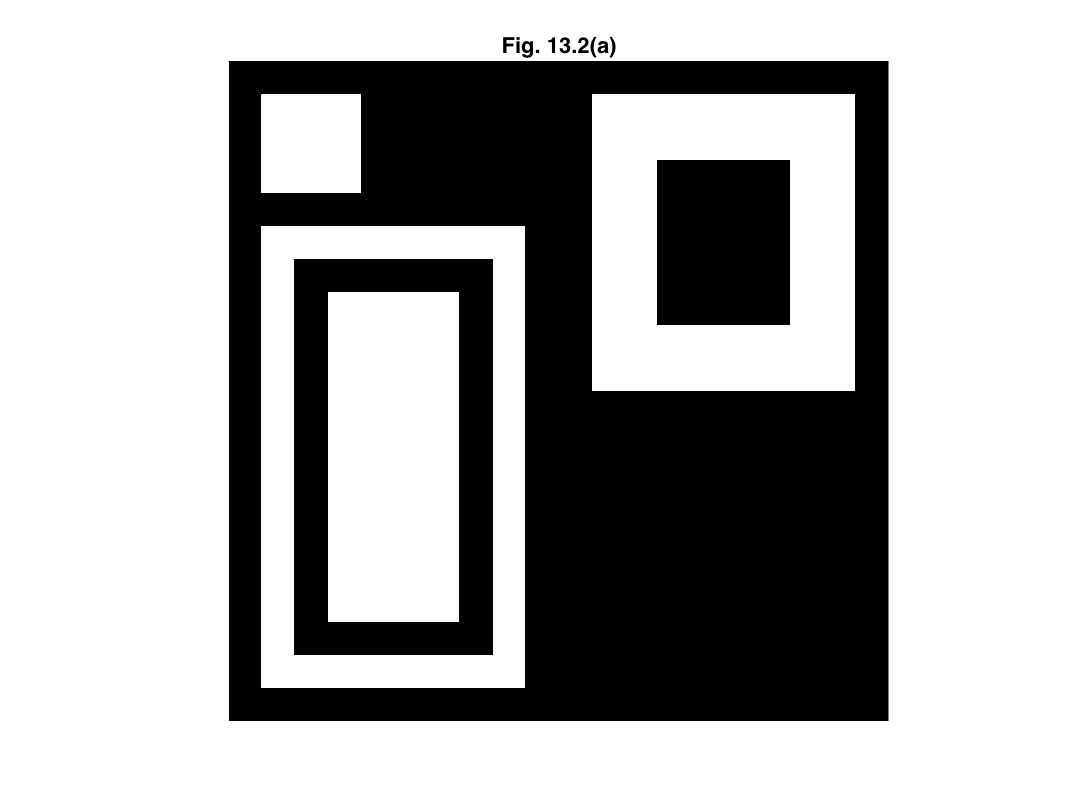

f = imread('nested-binary-regions.tif');
figure,imshow(f), title('Fig. 13.2(a)')


[B,L,NR,A] = bwboundaries(f);

% The function found a total of six internal and external boundaries:
disp(length(B))

     6




% There are four external boundaries:
disp(NR)

     4




% Two internal boundaries:
disp(length(B) - NR)

     2



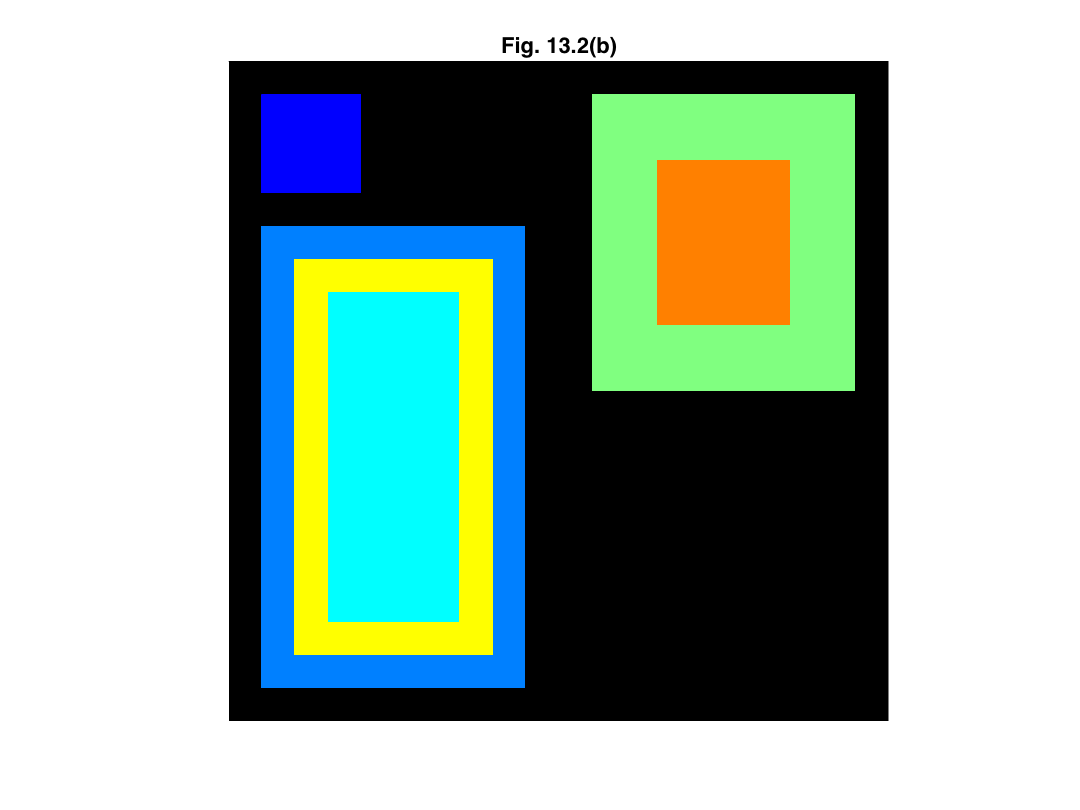


% Plot the elements of the label matrix L with a different color for each
% object using the jet color palette. We want zero values to map to black.

figure, imshow(label2rgb(L,@jet,[0,0,0]))
title('Fig. 13.2(b)')

Figure 13.2(b) shows the labeled regions and their labels (value of `k`). To view a region for any value of `k` (e.g., `k=4`) we use 

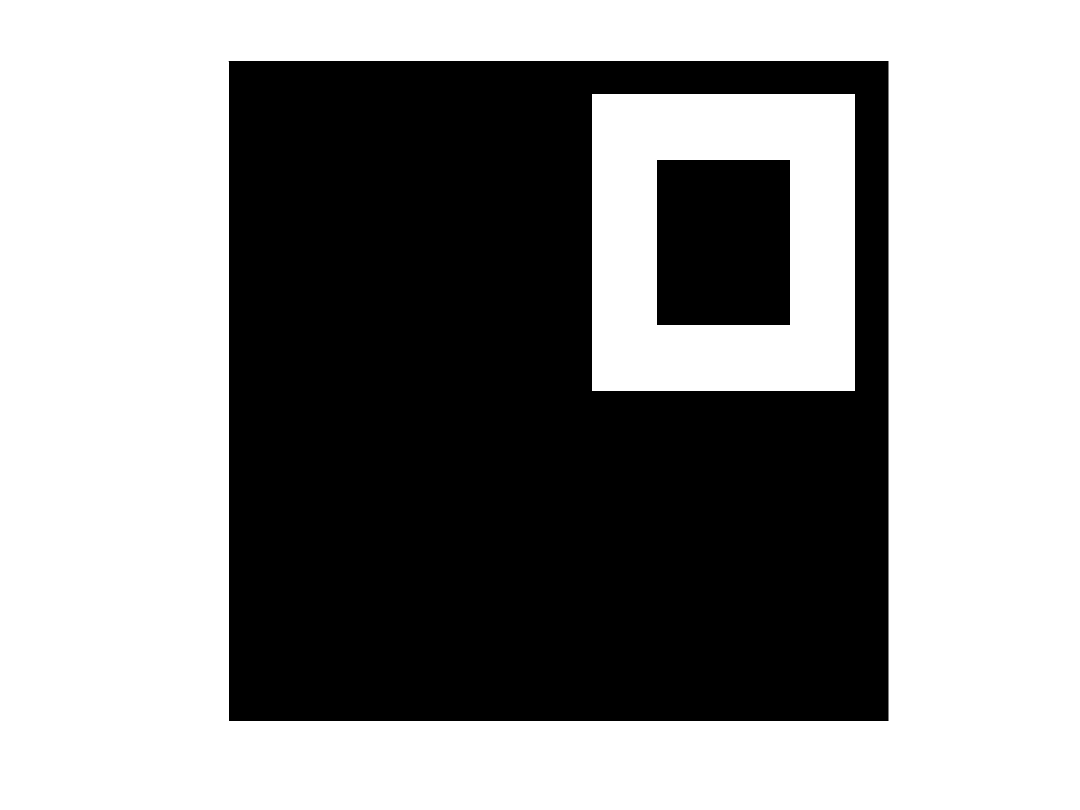

k = 4;
region = zeros(size(f));
region(L == k) = 1;
figure, imshow(region);

Figure 13.2(c) is the result of using the following commands: 				

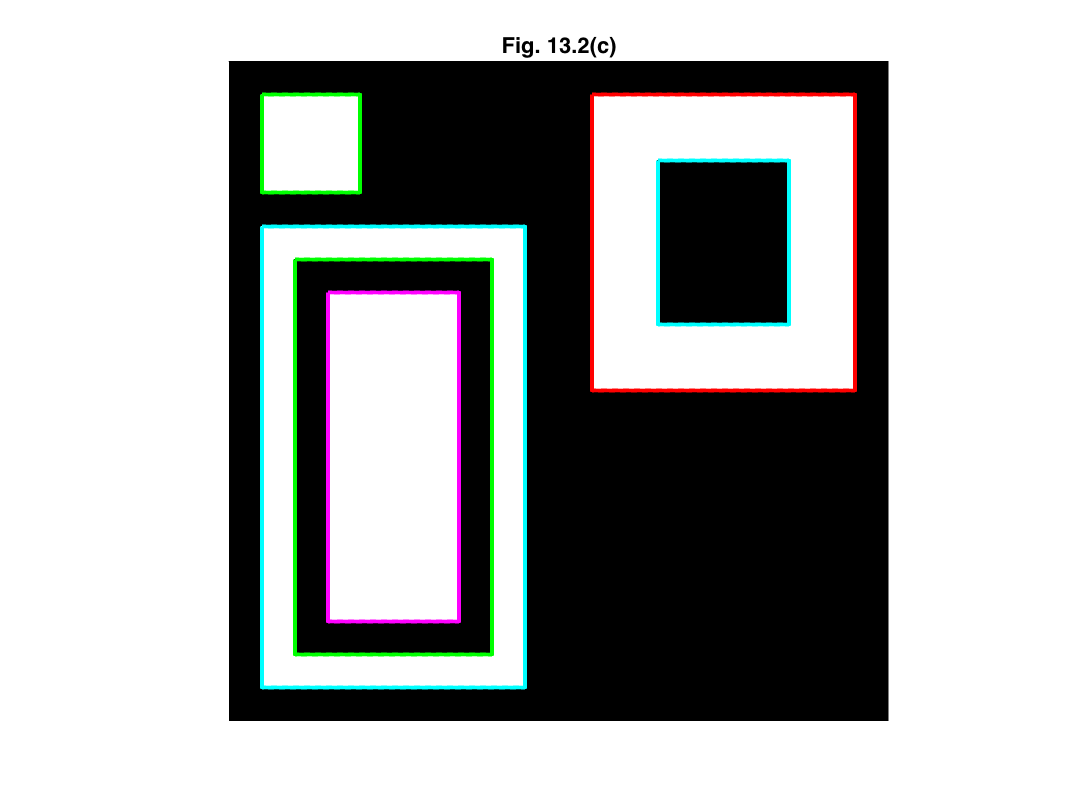

% Plot boundaries. Colors 'b' or 'y' are not used here because they
% are hard to see against black and white, respectively.

colors=['r' 'g' 'c' 'm'];
figure, imshow(f); hold on

for k = 1:length(B)
    boundary = B{k};    
    % Repeat colors if there are more regions than colors. If the number
    % of colors is greater than 1, idx starts with the second color.
    idx = mod(k,length(colors)) + 1;    
    plot(boundary(:,2),boundary(:,1),colors(idx),'LineWidth',2)
end
hold off
title('Fig. 13.2(c)')

Matrix `A` is of size `length(B) `$\times$ `length(B)` = $6 \times 6$. To see the entire matrix, we use `full(A)` because `A` is sparse: 

disp(full(A))

   0   0   0   0   0   0
   0   0   0   0   0   0
   0   0   0   0   1   0
   0   0   0   0   0   0
   0   1   0   0   0   0
   0   0   0   1   0   0



As noted earlier, the first NR cells in `B` refer to regions. In this case there are four regions (labeled 1–4) and two holes, labeled 5 and 6. Because `A(3,5)` = 1, we know that region 3 is a child of hole 5. Similarly, `A(5,2)` = 1 indicates that hole 5 is a child of region 2 and `A(6,4)` = 1 indicates that hole 6 is a child of region 4. We can obtain the same information by displaying the sparse matrix A directly: 

disp(A)

   (5,2)      1
   (6,4)      1
   (3,5)      1



% To determine if a region (e.g.,region 6) has a parent, we type 
labelBoundaryEnclosing = find(A(6,:));
disp(labelBoundaryEnclosing) 

     4



which indicates that the region enclosing region 6 is region 4. If region 6 had no parent, the result of the previous computation would have been empty: 

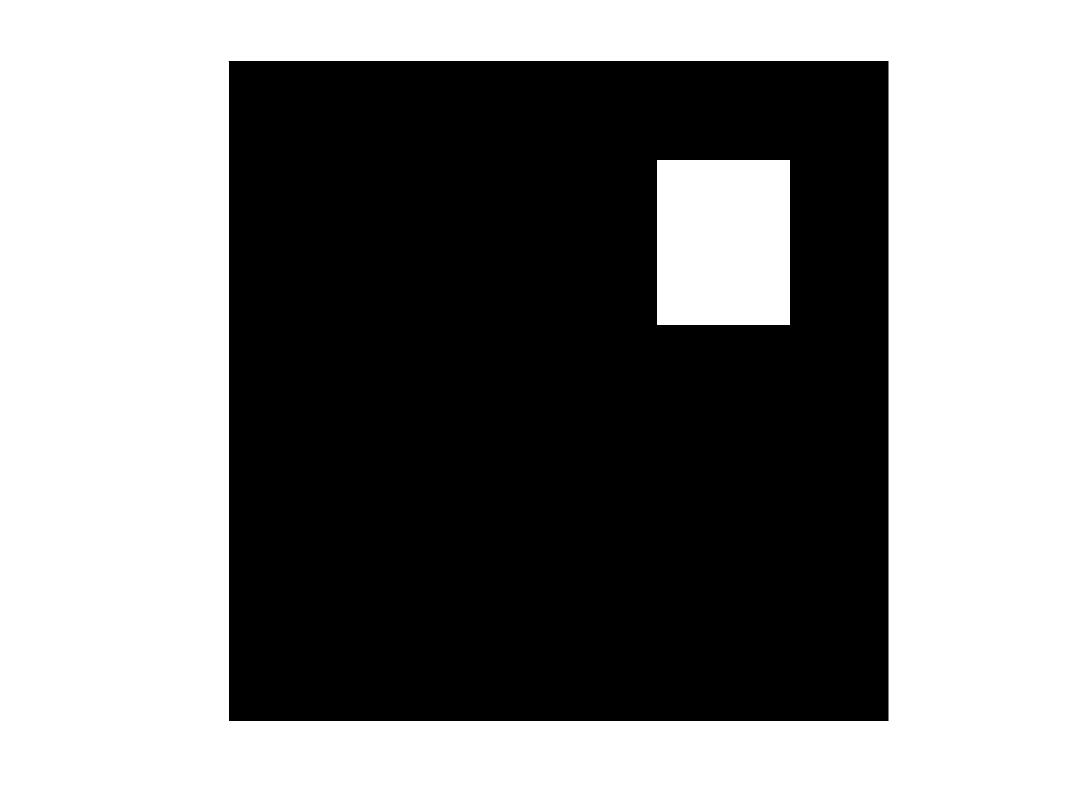

% To create an image that contains only one region, say, 6 again, we type
k = 6;
region = zeros(size(f));
region(L == k) = 1;

figure, imshow(region); % This would display a black image containing only region 6.